# Stair

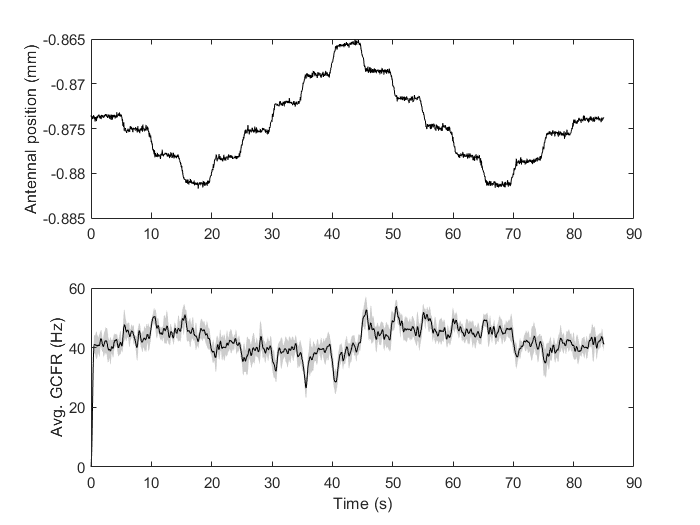

stim = -mean(P.antennal_movement, 1);
mid_point = length(stim)/2;
x = [5 9.5 14.5 19.5 24.5 29.5 34.5 39.5 44.5 49.5 54.5 59.5 64.5 69.5 74.5 79.5 84.5; ...
    5.5 10.5 15.5 20.5 25.5 30.5 35.5 40.5 45.5 50.5 55.5 60.5 65.5 70.5 75.5 80.5 85; ...
    5.5 10.5 15.5 20.5 25.5 30.5 35.5 40.5 45.5 50.5 55.5 60.5 65.5 70.5 75.5 80.5 85; ...
    5 9.5 14.5 19.5 24.5 29.5 34.5 39.5 44.5 49.5 54.5 59.5 64.5 69.5 74.5 79.5 84.5];

y_stim = repmat([min(stim)-0.005 min(stim)-0.005 max(stim)+0.005 max(stim)+0.005]', 1, 17);
y_gcfr = repmat([0 0 100 100]', 1,17);

figure; 
% for i=7:4:54 
%     i
    ax1 = subplot(2,1,1); plot(time(1:single_trial_length), stim, 'k'); hold on;    
%     patch(x,y_stim,[0.8500 0.3250 0.0980], 'FaceAlpha' , 0.3, 'EdgeColor', 'none');
    ylabel('Antennal position (mm)');
    
%     for i=7:5:54
%         i
%         fill([time(i*fs+1),time(i*fs+1), time((i+1)*fs), time((i+1)*fs)], [-0.88 -0.86 -0.86 -0.88], 'r', 'FaceAlpha',0.1);
%     end
    
    ax2 = subplot(2,1,2); 
%     plot(time(1:single_trial_length), P.avg_gcfr, 'k'); hold on;
    [lineOut, ~] = stdshade(P.gcfr,0.2,'k',time(1:single_trial_length)); %10 = (fs/L)*gcfr Hz
        lineOut.LineWidth  = 0.05;
%     patch(x,y_gcfr, [0.8500 0.3250 0.0980], 'FaceAlpha' , 0.3, 'EdgeColor', 'none');
%     for i=7:5:54
%         fill([time(i*fs+1),time(i*fs+1), time((i+1)*fs), time((i+1)*fs)], [0 100 100 0], 'r', 'FaceAlpha',0.1);
%     end
    ylabel('Avg. GCFR (Hz)');
    xlabel('Time (s)');
    
    xlim([0 40]);
    linkaxes([ax1 ax2], 'x');

    
% end



figure;

ax1 = subplot(2,1,1); plot(time(1:single_trial_length/2), stim(1:mid_point)); hold on;
plot(time(1:single_trial_length/2), fliplr(stim(mid_point+1:end)));
ylabel('Antennal position (mm)');

ax2 = subplot(2,1,2); plot(time(1:single_trial_length/2), P.avg_gcfr(1:mid_point)); hold on;
plot(time(1:single_trial_length/2), fliplr(P.avg_gcfr(mid_point+1:end)));
ylabel('Avg. GCFR (Hz)');
xlabel('Time (s)');

xlim([0 23]);
linkaxes([ax1 ax2], 'x');


## Ramp

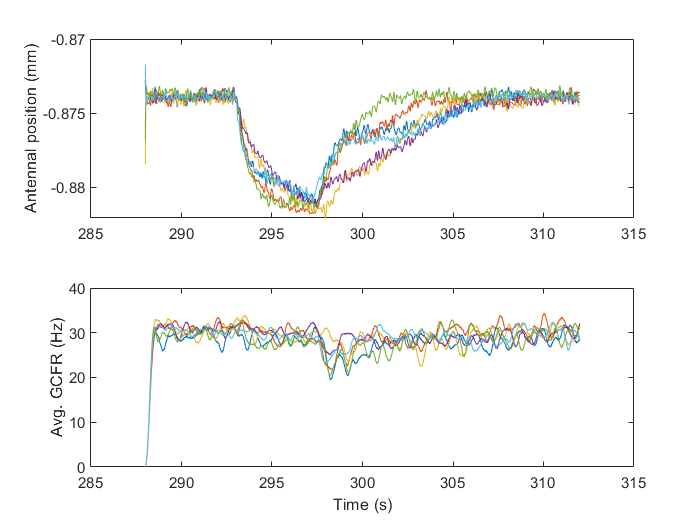

figure; 
for i=1:length(P)
    
    ax1 = subplot(2,1,1); plot(time(1:P(i).single_trial_length), -mean(P(i).antennal_movement, 1)); hold on;    
%     lgd = legend(["1 s", "2 s","0.5 s", "0.5 s"],"Location","northeast","NumColumns",1);
%     title(lgd, "Ramp duration");
    ylabel('Antennal position (mm)');
    
    ax2 = subplot(2,1,2); plot(time(1:P(i).single_trial_length), P(i).avg_gcfr); hold on;
    ylabel('Avg. GCFR (Hz)');
    xlabel('Time (s)');
    
    linkaxes([ax1 ax2], 'x');
    
end

## FR Vs Velocity

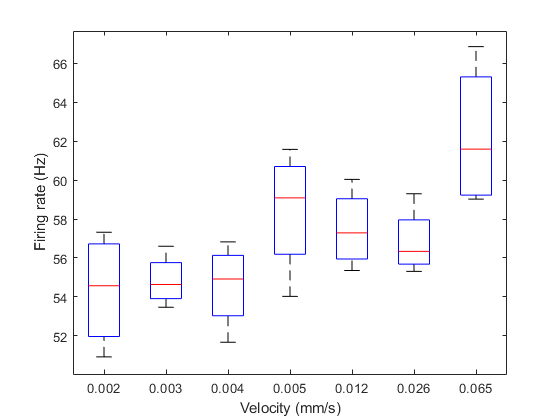

figure;
max_FR = [];
velocity = [];
max_FR_sorted = [];
velocity_sorted = [];
% raster = P.raster(start_stim:stop_stim);

for i=1:length(P)
   stim_name = split(P(i).stim_name);
   delta_t = str2double(stim_name(2));
   pos_low = mean(min(P(i).antennal_movement(:,1:3*fs),[],2));
   pos_high = mean(max(P(i).antennal_movement,[],2));
   amplitude = abs(pos_high - pos_low);
   velocity_values = repmat((amplitude/delta_t), [P(i).complete_trials,1]);
   velocity = [velocity; velocity_values];
   
  
   max_FR = [max_FR; max(P(i).gcfr, [], 2)];
   
 
end

[velocity_sorted, idx] = sort(velocity, 'ascend');
max_FR_sorted = max_FR(idx);
velocity_sorted = num2str(velocity_sorted, '%.3f');
boxplot(max_FR_sorted, velocity_sorted);
ylabel('Firing rate (Hz)');
xlabel('Velocity (mm/s)');

## Velocity Vs Latency

% raster = P.raster(start_stim:stop_stim);



## Step

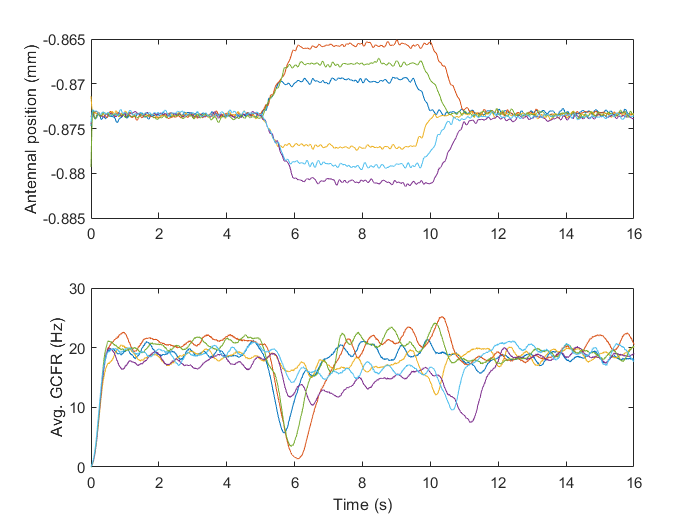

figure; 
for i=1:length(P)
    
    ax1 = subplot(2,1,1); plot(time(1:single_trial_length), -mean(P(i).antennal_movement, 1)); hold on;    
%     lgd = legend(["0.005 mm", "0.01 mm","-0.005 mm","-0.01 mm"],"Location","northeast","NumColumns",1);
%     title(lgd, "Step amplitude");
    ylabel('Antennal position (mm)');
    
    ax2 = subplot(2,1,2); plot(time(1:single_trial_length), P(i).avg_gcfr); hold on;
    ylabel('Avg. GCFR (Hz)');
    xlabel('Time (s)');
    
    linkaxes([ax1 ax2], 'x');
    
end

## PSTH

raster = P.raster;
sptimes = [];

for i=1:P.complete_trials
    sptimes = [sptimes find(raster(i,:)==1)];    
end

nbins = 100;
figure;
h = histogram(sptimes/fs, nbins);
h.FaceColor= 'k';
ax = gca;

mVal = max(h.Values) + round(max(h.Values)*0.1);
ax.YLim = [0 mVal];


stim_length = length(raster(1,:));
bin_duration = stim_length/nbins;
nbins_per_sec = 1000/bin_duration;

for i=1:length(ax.YTickLabel)
    label = str2num(ax.YTickLabel{i});
    conv = (label/length(sptimes))*nbins_per_sec;
    newLabel{i} = num2str(conv);
end

ax.YTickLabel = newLabel;
ax.YLabel.String = "Firing rate (Hz)";
ax.XLabel.String = "Time (s)";


